# **Plotting the binomial distribution: **

**Continued from PBOC day 2**

**Probability density function:**


$$P\left(x;p,n\right)=\left(\overset{n}{x} \right){\left(p\right)}^x {\left(1-p\right)}^{\left(n-x\right)}$$


where $\left(\underset{x}{n} \right)=\frac{n!}{x!\left(n-x\right)!}$

Relevant parameters: 

    n is the number of trials

    p is the probability of success in a single trial

The form we are going to use (specifically for the coin flip) is:

$P\left(n_H ;N\right)={\left(\frac{1}{2}\right)}^n \frac{N!}{n_H !\left(N-n_H \right)!}$; where N is the number of trials and $n_H$ is the number of heads. 

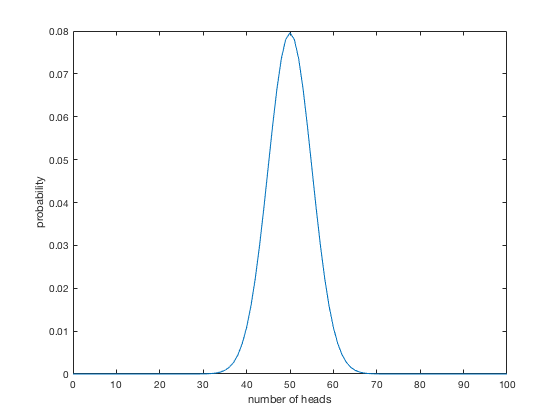

% define relevant parameters
n_trials = 100;
p_heads = 0.5;

x = 0 : 1 : n_trials;

%clear probability
%probability = zeros(1, n_trials+1);
% for i = 1 : n_trials
%   probability(i) = (p_heads).^n_trials .* ...
%       factorial(n_trials)./(factorial(x(i)).*factorial(n_trials-x(i)));    
% end


probability = (p_heads).^n_trials .* ...
    factorial(n_trials)./(factorial(x).*factorial(n_trials-x));

plot(x, probability)
xlabel('number of heads')
ylabel('probability')
hold off

What if we change the number of coin flips?

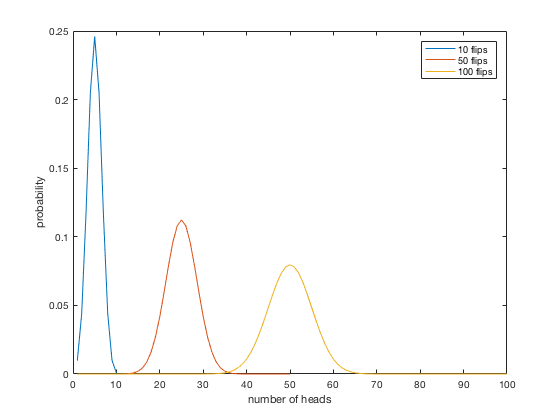

clear probability
% define relevant parameters
n_trials = [10, 50 100];
p_heads = 0.5;

for a = n_trials
    x = 1 : 1 : a;
    probability =  (p_heads).^a .* ...
        factorial(a)./(factorial(x).*factorial(a-x));  
    plot(x, probability)
    hold on
end
xlabel('number of heads')
ylabel('probability')
legend('10 flips', '50 flips', '100 flips')
hold off

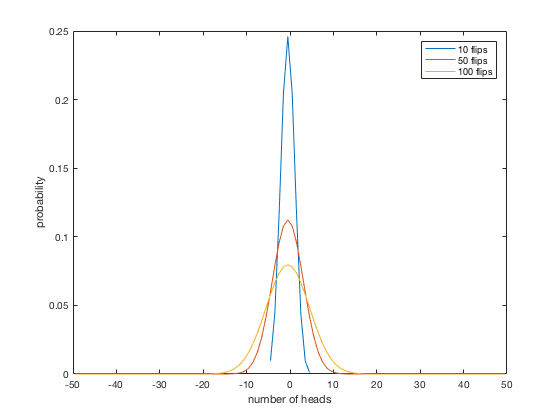


% to center this distribution at 0, subtract the mean number of heads
for a = n_trials
    x = 1 : 1 : a;
    probability =  (p_heads).^a .* ...
        factorial(a)./(factorial(x).*factorial(a-x));  
    plot(x-mean(x), probability)
    hold on
end
xlabel('number of heads')
ylabel('probability')
legend('10 flips', '50 flips', '100 flips')
hold off